# MATLAB dependencies

% There are several things you'll first need to do before running any of the analysis below.
% 1) Have a 2016b MATLAB or more recent versions installed
% 2) Detected events -- i.e. run your imaging data through the AQuA pipeline.
% 3) Have the following files on your path: dirPlus, detectBurst, readFts2,read_mixed_csv_ForPoskanzerData
% 4) (Optional) I use the colorbrewer color schemes. They can be downloaded here:
% https://www.mathworks.com/matlabcentral/fileexchange/34087-cbrewer---colorbrewer-schemes-for-matlab
% otherwise you can change the color arguments to any RGB you want.

## Defining directories

You need to add AQuA to your path in order to use its functions

softwareDir = 'Z:/.code/AQuA/'; %AQuA path
addpath(genpath(softwareDir));

%  read features from movies and put all the information in one structure called out
datDir = 'data/processed/v26/v26.aqua.data/'; %input directory where all of your processed movies are (aqua's .mat)
outDir = 'interim/v26.interim/';

spRes = 0.57998046875; %um/pix
tres = 0.55578697729921; %sec/frame

## Read features from all movies, store in a structure called out

% you might need to rewrite parts of this function or use your own function
% for reading in the data. When I was doing this analysis, we had AQuA
% writing the output in a strucutre called res. One layer deep was a
% substructure called fts and a layer deeper into fts was substructures like
% propagation, network, etc. The output format has changed a bit
% over time, so this function might be a little outdated. 

disp(pwd)

C:\Users\camer\Box\CMH\.repos\pfc


out = readFts(datDir);

1
  Column 1

    '121219_V26_54um_2…'
    'C:\Users\camer\Bo…'
    '13-Jan-2020 15:52…'
    [          731358550]
    [                  0]
    [         7.3780e+05]

  Column 2

    '121219_V26_59um_2…'
    'C:\Users\camer\Bo…'
    '13-Jan-2020 15:15…'
    [          550964166]
    [                  0]
    [         7.3780e+05]

  Column 3

    '121219_V26_test2-…'
    'C:\Users\camer\Bo…'
    '13-Jan-2020 14:41…'
    [          553613971]
    [                  0]
    [         7.3780e+05]

  Column 4

    '121219_V26_test2-…'
    'C:\Users\camer\Bo…'
    '13-Jan-2020 15:31…'
    [          558873125]
    [                  0]
    [         7.3780e+05]

  Column 5

    '121619_10min_67um…'
    'C:\Users\camer\Bo…'
    '09-Jan-2020 16:52…'
    [         1.3296e+09]
    [                  0]
    [         7.3780e+05]

  Column 6

    '121619_10min_67um…'
    'C:\Users\camer\Bo…'
    '13-Jan-2020 16:34…'
    [         1.4708e+09]
    [                  0]
    [         7.3780e+05]

2


Output argument "out" (and maybe others) not assigned during call to "readFts".

pp = struct2cell(dir([datDir, '**/*.mat']));
pp

pp = 6×6 cell array
    {'121219_V26_54um_2x-000_video_aqua.mat'                                                          }    {'121219_V26_59um_2x-000_video_aqua.mat'                                                          }    {'121219_V26_test2-000_video_aqua.mat'                                                          }    {'121219_V26_test2-000_video_aqua.mat'                                                                                     }    {'121619_10min_67um_nopupil_2x-002_video_aqua.mat'                                                             }    {'121619_10min_67um_nopupil_2x-002_video_aqua.mat'                                                              }
    {'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_54um_2x-000_video'}    {'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_59um_2x-000_video'}    {'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_test2-000_video'}    

 pp{2,3}

ans = 'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_test2-000_video'

 [pp{2,3}, pp{1,3}]

ans = 'C:\Users\camer\Box\CMH\.repos\pfc\data\processed\v26\v26.aqua.data\121219_V26_test2-000_video121219_V26_test2-000_video_aqua.mat'



testdirs = dir([datDir, '**/*.mat'])

testdirs = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


 A = size(pp,2)

A = 6

 B = size(pp,1)

B = 6

 testdirs.date{1}

Expected one output from a curly brace or dot indexing expression, but there were 6 results.

## Now reattempting after readFts modifications

out = readFts(datDir);

     1

below
121219_V26_54um_2x-000_video_aqua
     2

below
121219_V26_59um_2x-000_video_aqua
     3

below
121219_V26_test2-000_video_aqua
     4

below
121219_V26_test2-000_video_aqua
     5

below
121619_10min_67um_nopupil_2x-002_video_aqua
     6

below
121619_10min_67um_nopupil_2x-002_video_aqua


## Detect burst periods

%this function does a lot, so take from it what you need! most likely the
%mouse running data won't be useful so feel free to comment all those parts
%out (starting with the section 'read in optoswitch data' all the way to
%the end). 
features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 2
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 3
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 4
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 5
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 6
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222
   223
   224

Length of uT is13
 
jj is 1
i is 1
j is 7
 
Current things
uT is:
   213
   214
   215
   216
   217
   218
   219
   220
   221
   222


Index in position 1 exceeds array bounds (must not exceed 12).

Error in detectBurst (line 47)
                if nansum(out.propGrow{jj}{i}(j,:)) == 0


%now that you can index movies based on the burst period, you can do a lot
%of analysis! I'll show an example of just one thing you can do below.

x = 2 

x = 2


disp (['x is ', num2str(x)])

x is 2


The for loop in detect burst at line 47 was going out of index because of:

    for j = 2:length(uT)+1

The +1 was pushing it past index bounds. Removing the +1 and trying again. Noted Code:

%{

            Note: the for loop below is going past the lenght of uT by 1

            and throwing an error. I.e. uT has 12 elements, the list is

            trying to iterate to j=13 and throwing an error as is is out of

            bounds

            Question for Nicole, why `length+1` here? This is common for

            langs that index from 0 but is this common in MATLAB with

            idexing from 1? 

            %}

            %{            

            for j = 2:length(uT)+1

                disp(' ')

                disp('Current things')

                disp('uT is:')

                disp(uT)

                disp(['Length of uT is ', num2str(length(uT)+1)]) 

                disp(' ')

                disp(['jj is ', num2str(jj)])

                disp(['i is ', num2str(i)])

                disp(['j is ', num2str(j)])

            ### Rewriting this below without the +1 for length

            %}

            for j =2:length(uT)

                if nansum(out.propGrow{jj}{i}(j,:)) == 0

                    growthT(i,uT(k)) = 0;

                else

                    growthT(i,uT(k)) = nansum(out.propGrow{jj}{i}(j,:));

                end

                k=k+1;

            end

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

Unrecognized function or variable 'bursts'.

Error in detectBurst (line 137)
    for i = 1:length(bursts{jj})

It seems like no bursts are being detected in the videos as bursts is never built inside the for loop that starts at 120 below. Trying again with disps 

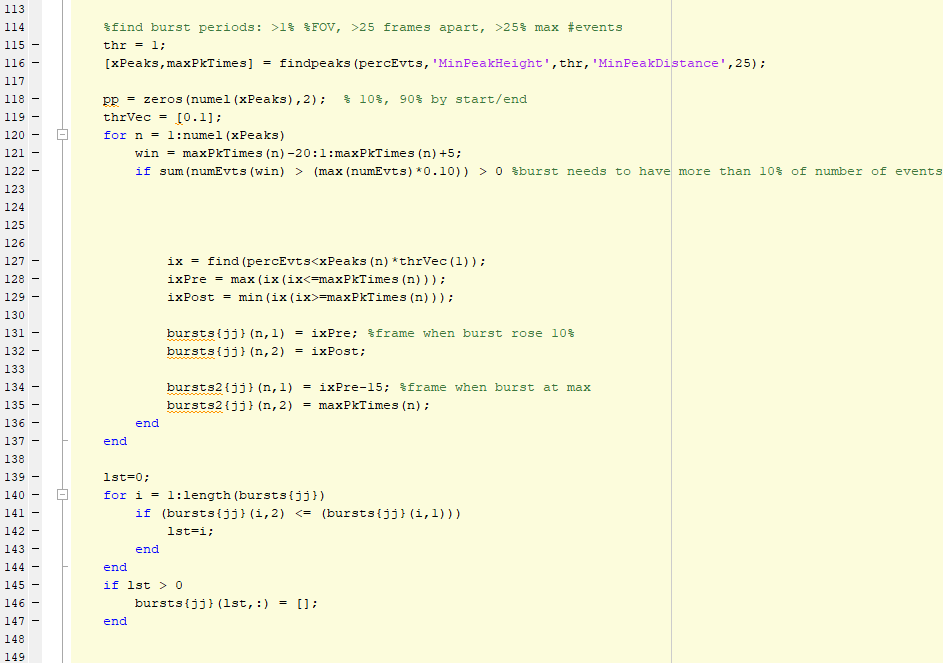

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

here1
xPeaks is
Num elements in xPeaks is 0
____________


Unrecognized function or variable 'bursts'.

Error in detectBurst (line 152)
    for i = 1:length(bursts{jj})

xPeaks is empty, has length 0. No peaks are being detected by findpeaks function...

Unsure if this is due to data or code. Going to try with data from Mike's video. 

Continuing here for now:

- findpeaks is from signal processing toolbox

- findpeaks is taking percEvts as arg, testing what percEvts looks like

features = out;
[bursts, burstStats] = detectBurst(features, spRes, tres, outDir);

percEvts are:
  Columns 1 through 7

     0     0     0     0     0     0     0

  Columns 8 through 14

     0     0     0     0     0     0     0

  Columns 15 through 21

     0     0     0     0     0     0     0

  Columns 22 through 28

     0     0     0     0     0     0     0

  Columns 29 through 35

     0     0     0     0     0     0     0

  Columns 36 through 42

     0     0     0     0     0     0     0

  Columns 43 through 49

     0     0     0     0     0     0     0

  Columns 50 through 56

     0     0     0     0     0     0     0

  Columns 57 through 63

     0     0     0     0     0     0     0

  Columns 64 through 70

     0     0     0     0     0     0     0

  Columns 71 through 77

     0     0     0     0     0     0     0

  Columns 78 through 84

     0     0     0     0     0     0     0

  Columns 85 through 91

     0     0     0     0     0     0     0

  Columns 92 through 98

     0     0     0     0     0     0     0

  Columns 99 through 10

Unrecognized function or variable 'bursts'.

Error in detectBurst (line 165)
    for i = 1:length(bursts{jj})

## PROPAGATION DIRECTION OVER TIME, single event example

%similar to figure 4c, top right. plot the event and its propagation
%direction over time

clear xLoc3D yLoc3D zLoc3D
for ii = 1:length(out.dff)
    for i = 1:length(out.locAbs{ii})
        aLocs = out.locAbs{ii}{i}; %single event
        [xLoc2D{ii}{i} yLoc2D{ii}{i} zLoc2D{ii}{i}] = (ind2sub([out.xSize{ii} out.ySize{ii} out.zSize{ii}], aLocs));
        xLoc2D{ii}{i} = out.xSize{ii}-xLoc2D{ii}{i};
    end
end

%index a single example event
ii=6; %movie index
j=3;  %burst index
i=44; %event index


plot(yLoc2D{ii}{i},xLoc2D{ii}{i},'s','Color',[0 174/255 239/255]); hold on;
axis([0 out.xSize{ii} 0 out.ySize{ii}])

pIdxG = cell(1,length(bursts));
offsetFr = bursts{ii}(j,2);
pIdxG{ii}{j} = zeros(round(1000),2);
propG = cell2mat(out.propGrow{ii}(i));
propG(isnan(propG))=0;
uTime = unique(zLoc2D{ii}{i});

clear sizeP turnaround taIdx on off timeOn
on = uTime(1);
off = uTime(end);
timeOn = on:1:off;

for jj = 1:size(timeOn,2) %time points of event
    %first column, N/S; second column E/W
    jIdx = timeOn(jj);
    
    northTime = propG(jj,1)-propG(jj,2);
    eastTime = propG(jj,4)-propG(jj,3);
    
    pIdxG{ii}{j}(jIdx,1) = pIdxG{ii}{j}(jIdx,1) + northTime; % (-): south, (+): north
    pIdxG{ii}{j}(jIdx,2) = pIdxG{ii}{j}(jIdx,2) + eastTime; % (-): west, (+): east
end


on = find(pIdxG{ii}{j},1);
off = find(pIdxG{ii}{j}(:,1),1,'last');
N = length(on:off);
C = linspecer(N,'sequential');

colormap(C);colorbar


%location at first frame
ii=6; %movie index
j=3;  %burst index
i=44; %event index

uTimeValues = unique(zLoc2D{ii}{i});
zLocIdx = find(zLoc2D{ii}{i} == uTimeValues(1)); %first frame
k(1) = nanmean(xLoc2D{ii}{i}(zLocIdx));
k(2) = nanmean(yLoc2D{ii}{i}(zLocIdx));

count=0; 
%index variable naming and renaming a bit dumb
kk=6; %movie index
jj=3;  %burst index

for ii = 1:length(timeOn)

    j = timeOn(ii);
    if  nansum(pIdxG{kk}{jj}(j,:)) ~= 0
        iii=ii-count;
        cInd = round(timeOn - bursts{kk}(jj,1));
        color = C(iii,:);
        plot([k(2) k(2)+pIdxG{kk}{jj}(j,2)],[k(1) k(1)+pIdxG{kk}{jj}(j,1)],'-','LineWidth',2,'Color',color);
        hold on;
        k = [k(1)+pIdxG{kk}{jj}(j,1) k(2)+pIdxG{kk}{jj}(j,2)];
        
        if pIdxG{kk}{jj}(j,2) > 0
            marker = '>';
        elseif pIdxG{kk}{jj}(j,2) < 0
            marker = '<';
        else
            marker = 'o';
        end
        
        if pIdxG{kk}{jj}(j,1) > 0 && pIdxG{kk}{jj}(j,1) > pIdxG{kk}{jj}(j,2)
            marker = '^';
        elseif pIdxG{kk}{jj}(j,1) < 0
            marker = 'v';
        else
            marker = 'o';
        end
        
        axis([0 out.xSize{kk} 0 out.ySize{kk}]); hold on;
        plot(k(2), k(1), 'Marker',marker,'Color',color,'MarkerSize',5,'LineWidth',jj);
    else
        count=count+1;
    end
end


title('posterior')
xlabel('anterior')
ylabel('lateral')
colormap(C);
c=colorbar;
c.Ticks = [1/length(timeOn):1/length(timeOn):1];
for i = 1:length(timeOn)
    j = timeOn(i);
    ar(i) = {num2str(j)};
end
c.TickLabels = ar;
ylabel(c,'medial')
set(gca,'fontsize',18)